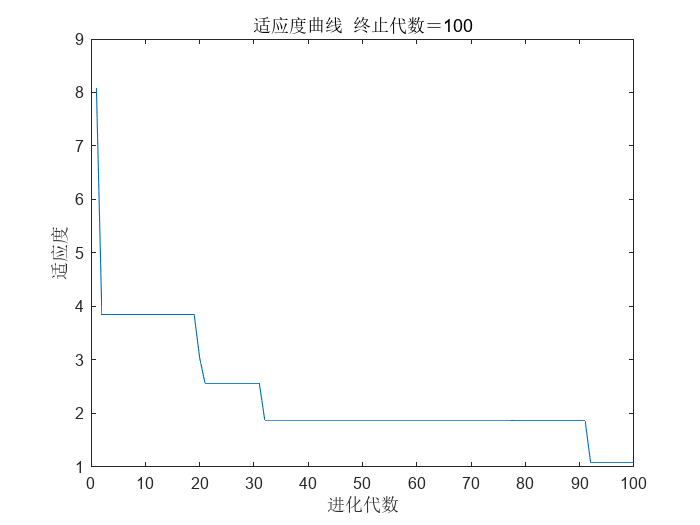

%% 清空环境
clc
tic

for i=1:4000
    input(i,:)=10*rand(1,2)-5;
    output(i)=input(i,1)^2+input(i,2)^2;
end

for i=1:4000
    input(i,:)=10*rand(1,2)-5;
    output(i)=input(i,1)^2+input(i,2)^2;
end
output=output';

save data input output

%读取数据
load data input output

%节点个数
inputnum=2;
hiddennum=4;
outputnum=1;
opnum=inputnum*hiddennum+hiddennum+hiddennum*outputnum+outputnum;
% 需要优化的参数个数

%% 训练数据预测数据提取及归一化
%从1到4000间随机排序
k=rand(1,4000);
[m,n]=sort(k);

%划分训练数据和预测数据
input_train=input(n(1:3900),:)';
output_train=output(n(1:3900),:)';
input_test=input(n(3901:4000),:)';
output_test=output(n(3901:4000),:)';

[inputn,inputps]=mapminmax(input_train);
[outputn,outputps]=mapminmax(output_train);

%构建网络
net=newff(inputn,outputn,hiddennum);

% 参数初始化
%粒子群算法中的两个参数
c1 = 1.49445;
c2 = 1.49445;

maxgen=100;   % 进化次数  
sizepop=30;   %种群规模

%个体和速度最大最小值
Vmax=1;
Vmin=-1;
popmax=5;
popmin=-5;

for i=1:sizepop
    pop(i,:)=5*rands(1,opnum);
    V(i,:)=rands(1,opnum);
    fitness(i)=PSO_BP_fun(pop(i,:),inputnum,hiddennum,outputnum,net,inputn,outputn);
end

% 个体极值和群体极值
[bestfitness bestindex]=min(fitness);
zbest=pop(bestindex,:);   %全局最佳
gbest=pop;    %个体最佳
fitnessgbest=fitness;   %个体最佳适应度值
fitnesszbest=bestfitness;   %全局最佳适应度值

%% 迭代寻优
for i=1:maxgen
    i;
    
    for j=1:sizepop
        
        %速度更新
        V(j,:) = V(j,:) + c1*rand*(gbest(j,:) - pop(j,:)) + c2*rand*(zbest - pop(j,:));
        V(j,find(V(j,:)>Vmax))=Vmax;
        V(j,find(V(j,:)<Vmin))=Vmin;
        
        %种群更新
        pop(j,:)=pop(j,:)+0.2*V(j,:);
        pop(j,find(pop(j,:)>popmax))=popmax;
        pop(j,find(pop(j,:)<popmin))=popmin;
        
        %自适应变异
        pos=unidrnd(opnum);
        if rand>0.95
            pop(j,pos)=5*rands(1,1);
        end
      
        %适应度值
        fitness(j)=PSO_BP_fun(pop(j,:),inputnum,hiddennum,outputnum,net,inputn,outputn);
    end
    
    for j=1:sizepop
    %个体最优更新
    if fitness(j) < fitnessgbest(j)
        gbest(j,:) = pop(j,:);
        fitnessgbest(j) = fitness(j);
    end
    
    %群体最优更新 
    if fitness(j) < fitnesszbest
        zbest = pop(j,:);
        fitnesszbest = fitness(j);
    end
    
    end
    
    yy(i)=fitnesszbest;    
        
end

%% PSO结果分析
plot(yy)
title(['适应度曲线  ' '终止代数＝' num2str(maxgen)]);
xlabel('进化代数');ylabel('适应度');

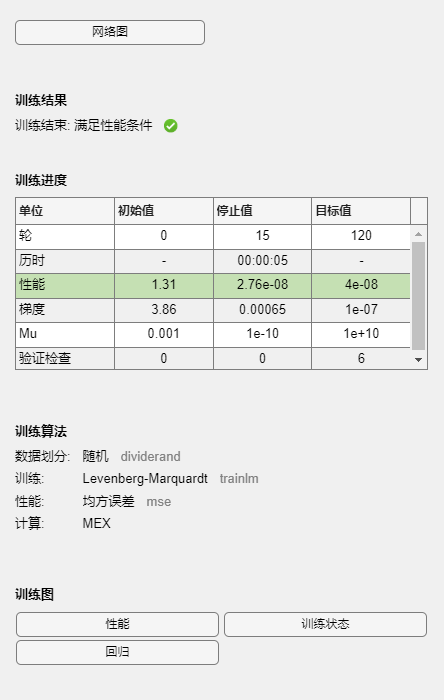


x=zbest;

%% 把最优初始阈值权值赋予网络预测
% %用PSO优化的BP网络进行值预测
w1=x(1:inputnum*hiddennum);
B1=x(inputnum*hiddennum+1:inputnum*hiddennum+hiddennum);
w2=x(inputnum*hiddennum+hiddennum+1:inputnum*hiddennum+hiddennum+hiddennum*outputnum);
B2=x(inputnum*hiddennum+hiddennum+hiddennum*outputnum+1:inputnum*hiddennum+hiddennum+hiddennum*outputnum+outputnum);

net.iw{1,1}=reshape(w1,hiddennum,inputnum);
net.lw{2,1}=reshape(w2,outputnum,hiddennum);
net.b{1}=reshape(B1,hiddennum,1);
net.b{2}=B2;

%% PSO-BP网络训练
%网络进化参数
net.trainParam.epochs=120;
net.trainParam.lr=0.005;
net.trainParam.goal=4e-8;

%网络训练
[net,per2]=train(net,inputn,outputn);


%% PSO-BP网络预测
%数据归一化
inputn_test=mapminmax('apply',input_test,inputps);
inputn_train=mapminmax('apply',input_train,inputps);
an=sim(net,inputn_test);
an1=sim(net,inputn_train);
test_PSOBP=mapminmax('reverse',an,outputps);
train_PSOBP=mapminmax('reverse',an1,outputps);

%% PSO-BP误差
error_PSOBP=test_PSOBP-output_test;
disp('PSO-BP results:');

PSO-BP results:


errorsum_PSOBP=sum(abs(error_PSOBP))

errorsum_PSOBP = 0.2667

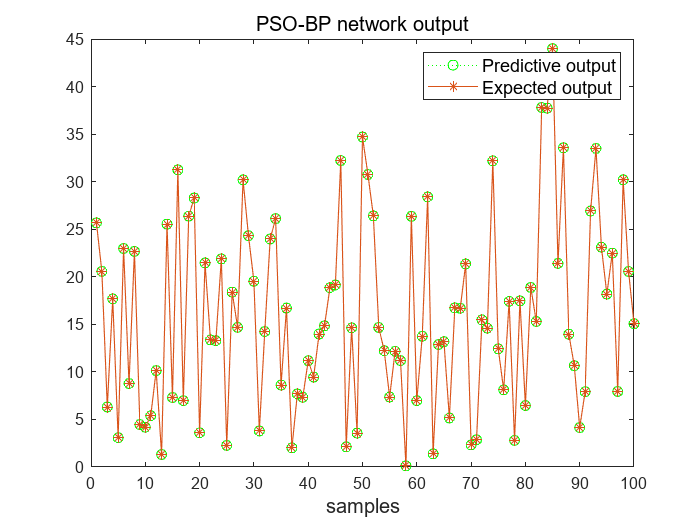


figure(1);
plot(test_PSOBP,':og');
hold on
plot(output_test,'-*');
legend('Predictive output','Expected output','fontsize',10.8);
title('PSO-BP network output','fontsize',12);
xlabel("samples",'fontsize',12);

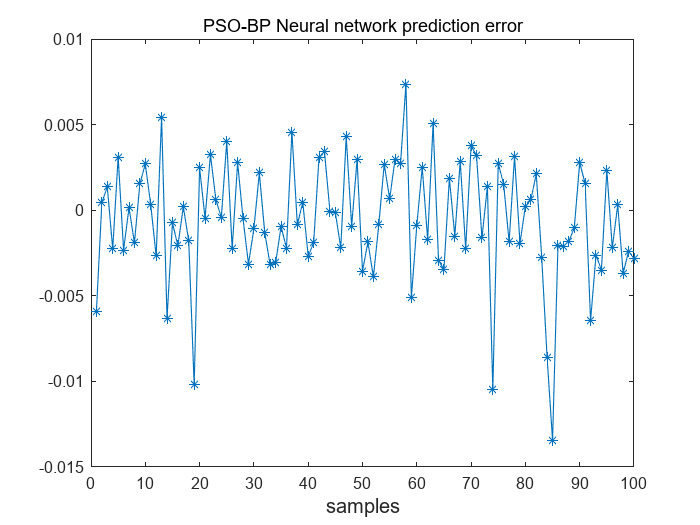


figure(2);
plot(error_PSOBP,'-*');
title('PSO-BP Neural network prediction error');
xlabel("samples",'fontsize',12);

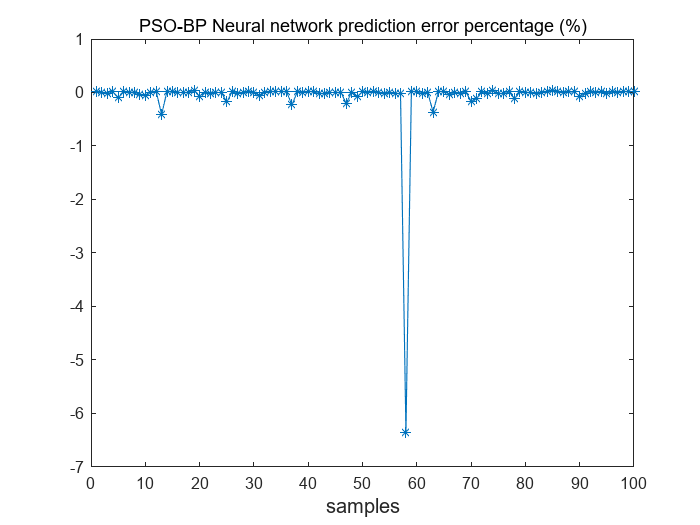


figure(3);
plot(100*(output_test-test_PSOBP)./output_test,'-*');
title('PSO-BP Neural network prediction error percentage (%)');
xlabel("samples",'fontsize',12);

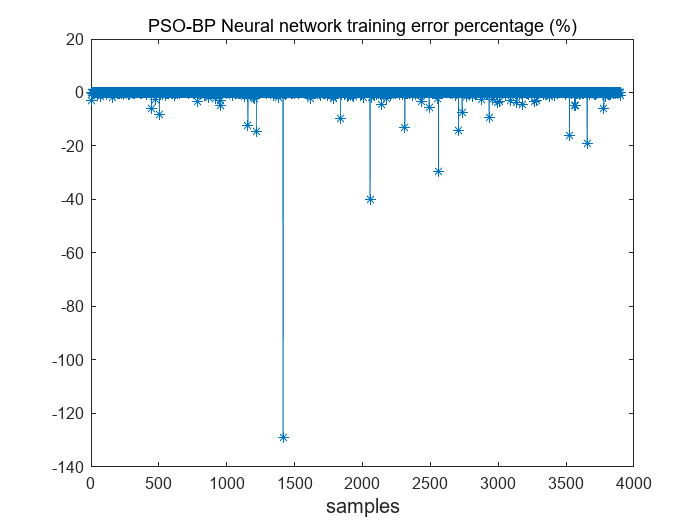


figure(4);
plot(100*(output_train-train_PSOBP)./output_train,'-*');
title('PSO-BP Neural network training error percentage (%)');
xlabel("samples",'fontsize',12);


toc

历时 176.205839 秒。


function error = PSO_BP_fun(x,inputnum,hiddennum,outputnum,net,inputn,outputn)

%提取
w1=x(1:inputnum*hiddennum);
B1=x(inputnum*hiddennum+1:inputnum*hiddennum+hiddennum);
w2=x(inputnum*hiddennum+hiddennum+1:inputnum*hiddennum+hiddennum+hiddennum*outputnum);
B2=x(inputnum*hiddennum+hiddennum+hiddennum*outputnum+1:inputnum*hiddennum+hiddennum+hiddennum*outputnum+outputnum);

%网络进化参数
net.trainParam.epochs=20;
net.trainParam.lr=0.1;
net.trainParam.goal=0.00001;
net.trainParam.show=100;
net.trainParam.showWindow=0;
 
%网络权值赋值
net.iw{1,1}=reshape(w1,hiddennum,inputnum);
net.lw{2,1}=reshape(w2,outputnum,hiddennum);
net.b{1}=reshape(B1,hiddennum,1);
net.b{2}=B2;

%网络训练
net=train(net,inputn,outputn);

an=sim(net,inputn);

error=sum(abs(an-outputn));
end


